# Kernel Ridge Regression

## Initailization (Dataset: data2)

- Zscore normalization

data=zscore(csvread('data2.csv'));
x=data(:,1:end-1);
y=data(:,end);

- Total number of data points

N=length(data);

- Visualization of the Data

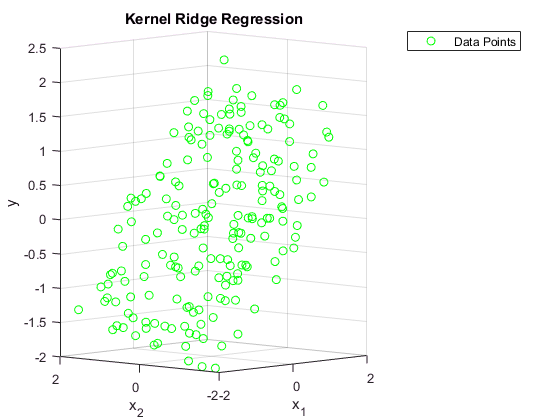

figure
scatter3(x(:,1),x(:,2),y,'g')
title('Kernel Ridge Regression')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Data Points')

## Various Kernels for above data

- Linear Kernel

K_linear=(x*x');

- Polynomial Kernel (Poly3)

K_poly3=(x*x').^3;

- Gaussian Kernel

K_gauss=zeros(N,N);
for j=1:N
 for i=1:N
    K_gauss(i,j)=exp(-norm(x(j,:)-x(i,:)));
 end
end

## Algorithm

- f_linear : Regression Function due to Linear Kernel

- f_poly3 : Regression Function due to Poly3 Kernel

- f_gaussian : Regression Function due to Gaussian Kernel

- mse : Mean Square Error

- A\b instead of inv(A)*b for faster computation

f_linear=zeros(N,1);
f_poly3=zeros(N,1);
f_gaussian=zeros(N,1);

mse=[];
intvl=0.1;

for lambda=intvl:intvl:1
    
    for i=1:N
        
        f_linear(i,1)= y'*((K_linear+ lambda*eye(N))\K_linear(i,:)');
        
        f_poly3(i,1)= y'*((K_poly3+ lambda*eye(N))\K_poly3(i,:)');
        
        f_gaussian(i,1)= y'*((K_gauss+ lambda*eye(N))\K_gauss(i,:)');
    end
    
     mse=[mse; norm(f_linear-y)^2/N, norm(f_poly3-y)^2/N, norm(f_gaussian-y)^2/N];
end

## Mean square error is the assessment measure for optimal Kernel

mse_=min(mse(:,1));
fprintf('Mean square error (Linear Kernel) : %f',mse_)

Mean square error (Linear Kernel) : 0.012884


mse_=min(mse(:,2));
fprintf('Mean square error (Poly3 Kernel) : %f',mse_)

Mean square error (Poly3 Kernel) : 0.141633


[mse_,gaussain_indx]=min(mse(:,3));
fprintf('"minimum" Mean square error (Gaussian Kernel) : %f',mse_)

"minimum" Mean square error (Gaussian Kernel) : 0.002413

## Optimal Langrangian Parameter

lambda_optimal=intvl*gaussain_indx

lambda_optimal = 0.1000

## Prediction Values (due to various Kernels)

Predicted=[y,f_linear,f_poly3,f_gaussian]

Predicted =    -0.1331   -0.4609   -0.0574   -0.3761
    0.6973    0.7131    0.4278    0.6600
   -1.1935   -1.1744   -0.6162   -1.1942
   -0.1428   -0.1200   -0.0012   -0.1087
    0.2828    0.3170    0.0516    0.2860
   -1.7101   -1.6915   -1.8376   -1.5723
   -1.4450   -1.4264   -1.1009   -1.4136
    0.1683    0.1778    0.2270    0.1592
   -0.1060   -0.0975    0.0461   -0.0645
   -0.0253   -0.1814   -0.0153   -0.1377


## Alpha & Dual, calculated as follows :

alpha=2*lambda_optimal*inv((K_gauss+lambda_optimal*eye(N)))*y

alpha =     0.1938
    0.0094
    0.0024
   -0.0493
    0.0010
   -0.0324
   -0.0024
   -0.0078
   -0.0689
    0.0872


W_alpha=y'*alpha -(1/4*lambda_optimal)*alpha'*K_gauss*alpha -(1/4)*alpha'*alpha

W_alpha = 4.3183

## Actual Vs Predicted Values

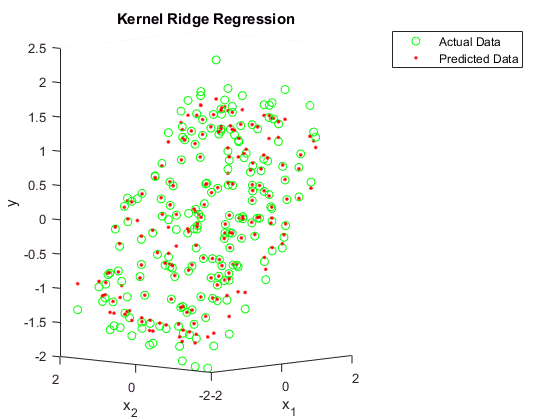

figure
hold on

scatter3(x(:,1),x(:,2),y,'g')
scatter3(x(:,1),x(:,2),f_gaussian,'.r')

title('Kernel Ridge Regression')
xlabel({'x_1'})
ylabel({'x_2'})
zlabel('y')
view([-47.1 4.4])
legend('Actual Data','Predicted Data')

hold off

% Bhartendu, Machine Learning & Computing